Vamos a usar MATLAB para hacer la convolución Richardson-Lucy y ver cuanto tiempo tarda.

%% Deconvolución Lucy-Richardson Matlab %%
%Hay que instalarse Image Processing Toolbox

% Cargar la imagen de prueba
img = single(imread('ImagenPrueba.jpg'));
%Cargamos la imagen borrosa y con ruido
img_n=single(imread("blurrednoisy_img.jpg"));

% Generar una PSF simple con un radio de apertura de 30
% Definir el tamaño de la imagen y el radio de apertura
img_size = size(img);
aperture_radius = 30;

% Generar una PSF simple
psf = fspecial('disk', aperture_radius);

% Normalizar la PSF
psf = psf / sum(psf(:));

% Ajustar el tamaño de la PSF para que coincida con el tamaño de la imagen
psf = padarray(psf, floor((img_size - size(psf)) / 2), 'both');

% Convertir la PSF a tipo de dato de precisión de coma flotante de 32 bits
psf = single(psf);

% Crear una versión borrosa y ruidosa de esa imagen
%img_b = conv2(img, psf, 'same'); % Borrosa
%img_n = img_b + sqrt(img_b) .* randn(size(img_b)); % Borrosa y ruidosa

% Deconvolucionar 2D con opciones predeterminadas

res = deconvlucy(img_n, psf, 30);
code_to_measure = @() deconvlucy(img_n, psf, 30);

% Medir el tiempo de ejecución
execution_time = timeit(code_to_measure);
disp(['Tiempo de ejecución: ', num2str(execution_time), ' segundos']);

Tiempo de ejecución: 0.61973 segundos


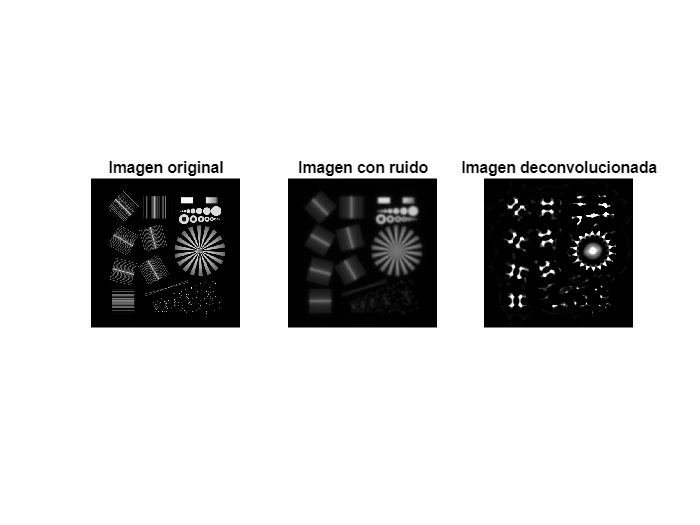




% Mostrar los resultados finales junto con la versión original y borrosa
figure;
subplot(1, 3, 1); imshow(uint8(img)); title('Imagen original');
subplot(1, 3, 2); imshow(uint8(img_n)); title('Imagen con ruido');
subplot(1, 3, 3); imshow(uint8(res)); title('Imagen deconvolucionada');


%Guardamos la figura resultante

%save_path = 'Path/donde/guardar/imagen.png';
%saveas(gcf, save_path);